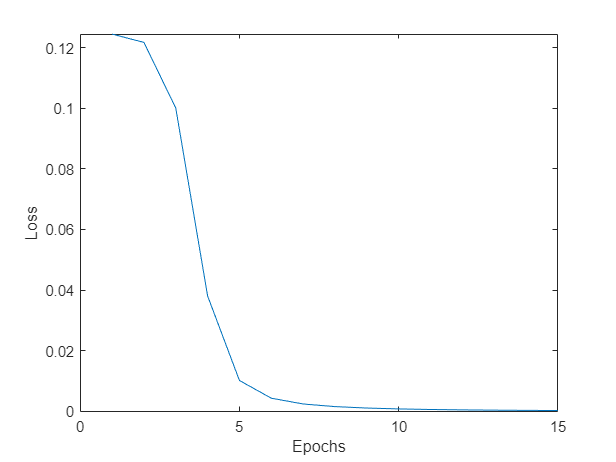

clear
close all

%parameters for the algorithm
%define the ammount of training samples in the dataset
numSamples = 70000;
lern_rate = 0.01;
epochs = 15;

%create dataset and according labels
x = randi(2,1,numSamples)-1;
y = randi(2,1,numSamples)-1;
true_output = double(xor(x,y));

%set up random weights
%generate 3 weigths per neuron: two for each input/activation and one for the bias
weightsHid = randn(2,3);
weightsOut = randn(1,3);

%set up presets for algorithm
inputs = ones(3,numSamples);        %the constant input 1 for the hidden layer biases is added here
inputs([1,2],:) = [x;y];
outputHid = ones(3,numSamples);     %the constant input 1 for the output layer bias is added here
averageLoss = zeros(1,epochs);
epochalLoss = 0;
wOutSum = 0;
wHidSum = 0;
previous_deltaWeightsOut = 0;
previous_deltaWeightsHid = 0;

tic
for e = 1:epochs
    for i = 1:numSamples
        %feedforward into hidden layer
        weightedSumHid = weightsHid * inputs(:,i);
        outputHid([1,2],i) = sig(weightedSumHid); %put the outputs of the two hidden neurons to the vector containing the bias 1 to be able to calculate the next layer
        %feedforward into output layer
        output = sig(weightsOut * outputHid(:,i));

        %calculate loss with square loss
        loss = 1/2 * (true_output(i) - output)^2;    %note: the factor 1/2 is there to simplify the loss functions derivative to -(target-guess). In the end by going in the negative diretion of the gradient the expression turns back to positve: deltaWeight = -lern_rate(-(target-guess)*bli*bla*blub) = lern_rate*(target - guess)*bli*bla*blub
        epochalLoss = epochalLoss + loss;

        %calculate errors for each layer
        output_error  = (true_output(:,i) - output) .* sigd(output);
        hidden_errors = weightsOut' * output_error;

        %calculate weights correction values
        deltaWeightsOut = output_error * outputHid(:,i)';
        deltaWeightsHid = hidden_errors(1:2) .* sigd(outputHid(1:2,i)) * inputs(:,i)';
        
        %update weights
        weightsHid = weightsHid + lern_rate * (deltaWeightsHid + previous_deltaWeightsHid*0.9);
        weightsOut = weightsOut + lern_rate * (deltaWeightsOut + previous_deltaWeightsOut*0.9);

        %store current weight change to be used the next momentum term in the update equation
        previous_deltaWeightsOut = deltaWeightsOut;
        previous_deltaWeightsHid = deltaWeightsHid;
    end
    averageLoss(e) = epochalLoss/numSamples;
    epochalLoss = 0;
end
%plot evolution of loss
plot(1:e,averageLoss)
ylim([0,max(averageLoss)])
ylabel('Loss')
xlabel('Epochs')


%test neural network
trueInput1  = [1;0;1];
shoudBeOne1 = sig(weightsOut*[sig(weightsHid*trueInput1);1])

shoudBeOne1 = 0.9739


trueInput2  = [0;1;1];
shoudBeOne2 = sig(weightsOut*[sig(weightsHid*trueInput2);1])

shoudBeOne2 = 0.9753


falseInput1  = [1;1;1];
shoudBeZero1 = sig(weightsOut*[sig(weightsHid*falseInput1);1])

shoudBeZero1 = 0.0191


falseInput2  = [0;0;1];
shoudBeZero2 = sig(weightsOut*[sig(weightsHid*falseInput2);1])

shoudBeZero2 = 0.0193

toc

Elapsed time is 5.280005 seconds.
